## GUIÃO 2.2

## 1. Considere a variável aleatória X correspondente a face que fica para cima no lançamento de 1 dado. Usando os valores teoricos:

## (a) Produza um grafico, em Matlab, que represente a função massa de probabilidade 1 de X;

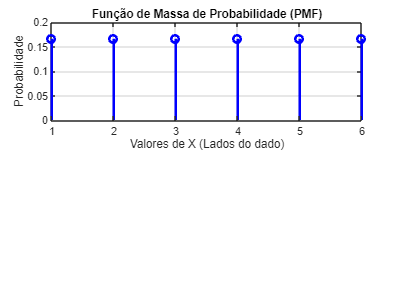

% Número de lados do dado
num_lados = 6;

% Probabilidade teórica de cada lado
probabilidade_lado = 1 / num_lados;

% Vetor de valores de X (os lados do dado)
valores_X = 1:num_lados;

% PMF (função de massa de probabilidade)
pmf = probabilidade_lado * ones(1, num_lados);

% Gráfico da PMF
subplot(2, 1, 1); % Divide a janela de gráficos em duas partes
stem(valores_X, pmf, 'b', 'LineWidth', 2);
title('Função de Massa de Probabilidade (PMF)');
xlabel('Valores de X (Lados do dado)');
ylabel('Probabilidade');
grid on;

## (b) Num segundo grafico da mesma figura, desenhe o gráfico da função de distribuição acumulada (use a função stairs do Matlab). 

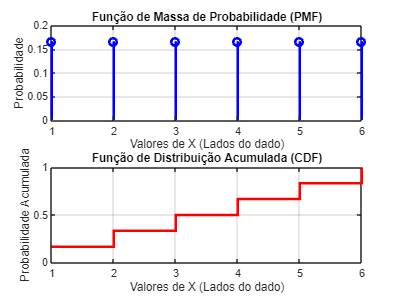

% CDF (função de distribuição acumulada)
cdf = cumsum(pmf);

% Gráfico da CDF
subplot(2, 1, 2);
stairs(valores_X, cdf, 'r', 'LineWidth', 2);
title('Função de Distribuição Acumulada (CDF)');
xlabel('Valores de X (Lados do dado)');
ylabel('Probabilidade Acumulada');
grid on;